# From LQOC to Quasi-Infinite Horizon MPC

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

 The classical LQOC formulation provides a systematic approach to designing a closed form state feedback control law which guarantees performance and nominal stability. However, the main difficulty associated with the classical LQOC formulation is its inability to handle operating constraints explicitly. Operating constraints, such as limits on manipulated inputs or on their rates of change, limits on controlled outputs arising out of product quality or safety considerations, are commonly encountered in any control application. Model Predictive Control (MPC), on the other hand, can explicitly deal with such operating constraints and also optimizes a performance measure which is similar to LQOC.  We used the Lyapunov's second method to establish the nominal stability of LQOC. Can we use this method to establish the nominal stability of MPC?     

 MPC can handle the operating constraints at the cost of increased online computational load by solving a constrained optimization problem at each sampling instant. When the constrained optimization problem is solved online at each sampling instant to compute the optimal control actions using a prediction model, the resulting implementation of MPC is referred to a Implicit MPC. On the other hand, in Explicit MPC implementation, solutions to the optimization problems for computing optimal control actions are solved offline as a family of state dependent piece-wise linear solutions. The online step consists of locating the correct control law based on the current state and then evaluating the control action**. **Both of these can handle constraints. We will focus only on implicit MPC in this course. 

In this lesson we present transition from the infinite horizon LQOC problem to a quasi-infinite horizon constrained MPC formulation. The Lyapunov's second method is used to establish the nominal stability of the constrained MPC. 

**Learning Objectives**

- To develop quasi-infinite horizon constrained MPC formulation starting from infinite horizon LQOC formulation

- Establish the nominal stability of infinite horizon LQOC formulation by including the terminal constraints 

## From LQOC Cost Function to MPC Cost Function

Consider infinite horizon LQOC problem as discussed in [module 3](matlab:open('../3.Linear_Qudratic_Optimal_Controller/L01_Linear_Quadratic_Optimal_Controller.mlx'))

 $\;\;\;\;\left\lbrace u^* \left(k\right):k=0,1,\ldotp \ldotp \infty \right\rbrace =\overset{\min }{u\left(0\right),\ldotp \ldotp u\left(j\right)\ldotp \ldotp \ldotp \ldotp } \left\lbrace \sum_{k=0}^{\infty } \left\lbrack {x\left(k\right)}^T W_x x\left(k\right)+{u\left(k\right)}^T W_u u\left(k\right)\right\rbrack \right\rbrace$   ------(1)


$$\textrm{Subject}\;\textrm{to}$$


$\;x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$  -------(2)

Let us assume that the system is reachable and a unique solution for the algebraic Riccati equation for chosen $\left(W_x ,W_u \right)\;$exists.  Now, taking motivation from the infinite horizon LQOC, we consider the following moving window controller formulation at the sampling instant $k$

 $\;{\mathrm{U}}_p^* \left(k\right)=\;\;\overset{\min }{{\mathrm{U}}_p \left(k\right)} \left\lbrace \sum_{j=0}^{\infty } \left\lbrack {z\left(k+j\right)}^T W_x z\left(k+j\right)+{u\left(k+j|k\right)}^T W_u u\left(k+j|k\right)\right\rbrack \right\rbrace$   ------(3)


$$\textrm{Subject}\;\textrm{to}$$


$\begin{array}{l}
\;z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j\right)\\
\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp \infty \;\;\textrm{with}\;z\left(k\right)=x\left(k\right)\;
\end{array}$  -------(4)

$u\left(k+j|k\right)=0\;\;\textrm{for}\;j=p,p+1,\ldotp \ldotp \ldotp \ldotp \infty$  ------(5)

Note that the set ${\mathrm{U}}_p \left(k\right)$ is defined as  

${\mathrm{U}}_p \left(k\right)=\left\lbrace u\left(k|k\right),u\left(k+1|k\right),\ldotp \ldotp \ldotp ,u\left(k+p-1|k\right)\right\rbrace$ -----(6)

 where the notation $\left(k+j|k\right)$ indicates that $u\left(k+j|k\right)$ represents the decision variable of the optimization problem formulated at instant $k$. Thus, $u\left(k+j|k\right)$is not the actual input to the system, $u\left(k+j\right)$, at instant  $\left(k+j\right)$. Note that inclusion of constraints (5) implies that the predictions evolve as 


$$\;z\left(k+j+1\right)=\Phi z\left(k+j\right)\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp \infty \;\;$$
 

that is 

$z\left(k+j\right)=\Phi^{j-1} z\left(k+p\right)$ $\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp \infty$   ------(7)

Thus, using the input constraints (5), the cost function (3) can be expressed as

$\begin{array}{l}
J\left(k,\infty \right)=\sum_{j=0}^{\infty } \left\lbrack {z\left(k+j\right)}^T W_x z\left(k+j\right)+{u\left(k+j\right)}^T W_u u\left(k+j\right)\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\sum_{j=0}^{p-1} \left\lbrack {z\left(k+j\right)}^T W_x z\left(k+j\right)+{u\left(k+j\right)}^T W_u u\left(k+j\right)\right\rbrack +J\left(k+p,\infty \right)
\end{array}$   ------(8)

where 

$J\left(k+p,\infty \right)=\sum_{j=p}^{\infty } \left\lbrack {z\left(k+j\right)}^T W_x z\left(k+j\right)\right\rbrack ={z\left(k+p\right)}^T \left(\sum_{j=0}^{\infty } \left\lbrack {{\left(\Phi^j \right)}^T W}_x \;\left(\Phi^j \right)\right\rbrack \;\right)z\left(k+p\right)\;\;$ ------(9)

The term $J\left(k+p,\infty \right)$ is replaced by ${z\left(k+p\right)}^T W_{\infty } z\left(k+p\right)$ and the infinite horizon cost function can be expressed as a quasi-infinite horizon cost function as follows

$J\left(k,\infty \right)=$$\sum_{j=0}^{p-1} \left\lbrack {z\left(k+j\right)}^T W_x z\left(k+j\right)+{u\left(k+j\right)}^T W_u u\left(k+j\right)\right\rbrack +{z\left(k+p\right)}^T W_{\infty } z\left(k+p\right)\;$------(10)

To carry out this transformation, we consider two scenarios, stable and unstable systems.

### Stable Systems

In this case the eigenvalues of $\Phi$ are either strictly inside the unit circle or on the unit circle. The matrix $W_{\infty }$ defined as 

$W_{\infty } =\sum_{j=0}^{\infty } \left\lbrack {{\left(\Phi^j \right)}^T W}_x \;\left(\Phi^j \right)\right\rbrack \;$ ------(11)

 can be found by solving the following discrete Lyapunov equation

$\Phi^T W_{\infty } \Phi -$$W_{\infty }$=$-W_x$  ------(12)

Note that $W_{\infty }$ can be positive semidefinite for marginally stable systems. 

### Unstable Systems

In this case, some of the eigenvalues of $\Phi$ are outside the unit circle. Thus, we partition the Jordan form matrix $\Phi$ into stable and unstable parts as follows 

$\Phi =\Psi J\Psi^{-1} =\left\lbrack \begin{array}{cc}
\Psi_u  & \Psi_s 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
J_u  & \left\lbrack 0\right\rbrack \\
\left\lbrack 0\right\rbrack  & J_s 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\bar{\Psi_u } \\
\bar{\Psi_s } 
\end{array}\right\rbrack$  ------(13)

The unstable eigenvalues are in $J_u$. We define stable ($\xi_s$) and unstable ($\xi_u$) modes of the system using the following variable transformation 

$\left\lbrack \begin{array}{c}
\xi_u \\
\xi_s 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\bar{\Psi_u } \\
\bar{\Psi_s } 
\end{array}\right\rbrack z$  ------(14)

and the system dynamics in terms of the transformed variables is represented as 

$\left\lbrack \begin{array}{c}
\xi_u \left(k+1\right)\\
\xi_s \left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
J_u  & \left\lbrack 0\right\rbrack \\
\left\lbrack 0\right\rbrack  & J_s 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\xi_u \left(k\right)\\
\xi_s \left(k\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\bar{\Psi_u } \\
\bar{\Psi_s } 
\end{array}\right\rbrack \Gamma u\left(k\right)$  ------(15)

Now, for converting $J\left(k,\infty \right)$ to quasi-infinite horizon cost function requires inclusion of additional constraint on the state at instant $\left(k+p\right)$ in the future 

$\xi_u \left(k+p\right)=\bar{\Psi_u } z\left(k+p\right)=\bar{0}$  ------(16)

This constraint implies that the unstable modes are brought to zero at $k+p$ and remain at the origin for $k>p$. Therefore, the input domain must consist of $U_f \left(k\right)$ that can bring the unstable modes of the system to the origin. Now, for $k>p$, the predictions evolve as 

$\left\lbrack \begin{array}{c}
\xi_u \left(k+1\right)\\
\xi_s \left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
J_u  & \left\lbrack 0\right\rbrack \\
\left\lbrack 0\right\rbrack  & J_s 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\bar{0} \\
\xi_s \left(k\right)
\end{array}\right\rbrack$ ------(17)

that is $J\left(k+p,\infty \right)$ can be computed by solving for the following discrete time Lyapunov equation 

$J_s^T \Pi_{\infty } J_s -$$\Pi_{\infty } \;{=\;\left(\Psi_s \right)}^T \;W_x \left(\Psi_s \right)\;$  ------(18) 

where $\Pi_{\infty }$ is defined as 

$\Pi_{\infty } =\sum_{j=0}^{\infty } {\left(\Psi_s J_s^j \right)}^T \;W_x \left(\Psi_s J_s^j \right)\;$ ------(19)

and 

$W_{\infty } ={\left(\bar{\Psi_s } \right)}^T \Pi_{\infty } \left(\bar{\Psi_s } \right)$   ------(20)

Moral of the story is that conversion of infinite horizon cost function to a quasi-infinite horizon cost function involves inclusion of additional terminal constraint (16) in the MPC formulation. Note that the prediction horizon needs to be sufficiently large, i.e. $p\gg n$, for a feasible solution to exist when the terminal constraint is included.  

## Nominal Stability of Quasi-Infinite Horizon Constrained MPC

To establish closed loop stability, we introduce the following assumptions: 

**Assumption 1:** There is no model plant mismatch and unmeasured disturbances are absent. The plant/system evolves according to

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$-----------(21)

**Assumption 2:** The true states are perfectly  known/measured at every sampling instant $k$

In addition, we now introduce a terminal constraint, $z\left(k+p\right)=\bar{0}$, which is even more stringent than equation (16).  To simplify the notations in the derivation, we denote ${\|x\|}_W^2 =x^T W\;x$ and the MPC cost function is represented as 

$J\left\lbrack x\left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)\right\|}^2 }_{W_x } +{{\left\|u\left(k+j|k\right)\right\|}^2 }_{W_u } \right\rbrace$  ------(22)

Note that inclusion of the terminal constraint implies ${{\left\|z\left(k+p\right)\right\|}^2 }_{W_{\infty } } =0$. As a consequence, the terminal cost is not considered in the later part of this section.  

Thus, the regulatory MPC at instant $k$ is formulated as follows


$$\;$$
  
$${\mathrm{U}}_p^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_p \left(k\right)} \;\;\;\left\lbrack J\left(x\left(k\right),U_f \left(k\right)\right)\right\rbrack$$
   

Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)\\
\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp ,p-1\;\textrm{with}\;z\left(k\right)=x\left(k\right)
\end{array}$   ------(23) 

$u_L \le u\left(k+j|k\right)\le u_H$   for$j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$   ------(24)

$z\left(k+p\right)=\bar{0}$  ------(25)

Let us select a candidate Lyapunov function as follows 

$V\left\lbrack x\left(k\right)\right\rbrack =J\left\lbrack x\left(k\right),U_f \left(k\right)\right\rbrack \;$  ------(26)

It is clear that $V\left\lbrack x\left(k\right)\right\rbrack$ is a positive definite and radially unbounded function of $x\left(k\right)$. For the chosen candidate Lyapunov function, we need to establish that

$\Delta V\left\lbrack x\left(k\right)\right\rbrack =J\left\lbrack x\left(k+1\right),{\mathrm{U}}_p \left(k+1\right)\right\rbrack -J\left\lbrack x\left(k\right),{\mathrm{U}}_p \left(k\right)\right\rbrack <0$  -------(27)

Let us assume that an optimal solution 

${\mathrm{U}}_p^* \left(k\right)=\left\lbrace u^* \left(k|k\right),u^* \left(k+1|k\right),\ldotp \ldotp \ldotp ,u^* \left(k+p-1|k\right)\right\rbrace$ ------(28)

 exists at instant $k$ for the MPC problem and can be found by application of a QP solver. Further, application of  $U_f^* \left(k\right)$ to the prediction model yields the optimum state trajectory predictions 

$\begin{array}{l}
z^* \left(k+j+1\right)=\Phi z^* \left(k+j\right)+\Gamma u^* \left(k+j|k\right)\;\;\textrm{for}\;\;\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1\\
{\;\;\;\;\;\;\;\;z}^* \left(k+p\right)=\bar{0} 
\end{array}$  ------(29)  

such that the terminal constraint is satisfied, and the optimum cost function at instant $k$ is 

$J\left\lbrack x\left(k\right),{\mathrm{U}}_p^* \left(k\right)\;\right\rbrack =\sum_{j=0}^{p-1} \left\lbrace {{\left\|z^* \left(k+j\right)\right\|}^2 }_{W_x } +{{\left\|u^* \left(k+j|k\right)\right\|}^2 }_{W_u } \right\rbrace$----------(30)

Note that, due to presence of constraints, $u^{\ast }(k|k)$ is some nonlinear function of the current state $x\left(k\right)$, say $u^{\ast }(k|k)=g[x(k)]$. In the moving horizon framework, we choose $u(k)=u^{\ast }(k|k)$ and the plant/system (1) evolves from instant $k$ to $k+1$ as follows  

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)=\Phi x\left(k\right)+\Gamma g\left\lbrack x\left(k\right)\right\rbrack$  ------(31)

At sampling instant $k+1$, the optimization problem reformulated is solved again over window $\left\lbrack k+1,k+p+1\right\rbrack$ using measurement $x\left(k+1\right)$. Let decision variables for this optimization problem be denoted as  

${\mathrm{U}}_p \left(k+1\right)=\left\lbrace u\left(k+1|k+1\right),u\left(k+21|k+1\right),\ldotp \ldotp \ldotp ,u\left(k+p|k+1\right)\right\rbrace$ -----(32)

To solve the optimization problem, we need to pick up an initial feasible guess solution $U_f \left(k+1\right)$, i.e. a guess that satisfies the terminal constraint at instant $k+1$.  Now let us construct a non-optimal but feasible solution**,** ${\mathrm{U}}_p \left(k+1\right)$, using ${\mathrm{U}}_p^* \left(k\right)$ as follows 

$\begin{array}{l}
\;\;\;u\left(k+i|k+1\right)=u^* \left(k+i|k\right)\;\;\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp p-1\;\;\;\\
\;\;\;\;u\left(k+p|k+1\right)=\bar{0} 
\end{array}$    ------(33)

Since there is no model plant mismatch and $u(k)=u^{\ast }(k)$, it follows that  ${x\left(k+1\right)=z}^* \left(k+1\right)$ and the feasible state sequence generated by implementing this feasible $U_f \left(k+1\right)$ is given by 

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;z\left(k+j\right)=z^* \left(k+j\right)\;\textrm{for}\;\;j=1,2,\ldotp \ldotp \ldotp \ldotp p\;\\
z\left(k+p+1\right)=\Phi z^* \left(k+p\right)+\Gamma u\left(k+p|k+1\right)=\bar{0} 
\end{array}$  ------(34) 

where $\left\lbrace z^* \left(k+j\right)\right\rbrace$ are given by the set of equation (29). Now, let the optimal solution of the QP problem at instant $\left(k+1\right)$ be denoted as 

${\mathrm{U}}_p^* \left(k+1\right)=\left\lbrace u^* \left(k+1|k+1\right),u^* \left(k+2|k+1\right),\ldotp \ldotp \ldotp ,u^* \left(k+p|k+1\right)\right\rbrace$ ------(35)

and let $J\left\lbrack x\left(k+1\right),{\mathrm{U}}_p^* \left(k+1\right)\;\right\rbrack$denote the optimum cost at instant $\left(k+1\right)$. Now, for the chosen feasible solution (33), the following inequality holds

$J[x(k+1),U_{f}^{\ast }(k+1)]\le J[x(k+1),U_{f}(k+1)]$--------(36)


$$J\left\lbrack x\left(k+1\right),{\mathrm{U}}_p^* \left(k+1\right)\;\right\rbrack \le J\left\lbrack x\left(k+1\right),{\mathrm{U}}_p \left(k+1\right)\;\right\rbrack$$


and this implies that 

$\begin{array}{l}
\Delta V\left\lbrack x\left(k\right)\right\rbrack =J\left\lbrack x\left(k+1\right),{\mathrm{U}}_p^* \left(k+1\right)\;\right\rbrack -J\left\lbrack x\left(k\right),{\mathrm{U}}_p^* \left(k\right)\;\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\le J\left\lbrack x\left(k+1\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack -J\left\lbrack x\left(k\right),{\mathrm{U}}_p^* \left(k\right)\;\right\rbrack 
\end{array}$    -------(37)

Since, the first $p-1$ sub-vectors of $U_f \left(k+1\right)$ and $U_f^* \left(k\right)$ are common**, **from the set of equations (23) and (34), it follows that 

$\begin{array}{l}
J\left\lbrack x\left(k+1\right),U_f \left(k+1\right)\;\right\rbrack =\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j+1\right)\right\|}^2 }_{W_x } +{{\left\|u\left(k+j+1|k+1\right)\right\|}^2 }_{W_u } \right\rbrace \;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\sum_{j=1}^{p-1} \left\lbrace {{\left\|z^* \left(k+j\right)\right\|}^2 }_{W_x } +{{\left\|u^* \left(k+j|k\right)\right\|}^2 }_{W_u } \right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=J\left\lbrack x\left(k\right),{\mathrm{U}}_p^* \left(k\right)\right\rbrack -\left\lbrack {\left\|x\left(k\right)\right\|}_{W_x }^2 +{\left\|u^* \left(k|k\right)\right\|}_{W_u }^2 \right\rbrack 
\end{array}$ ------(38) 

This implies that the difference in the cost functions is 

$J\left\lbrack x\left(k+1\right),{\mathrm{U}}_p \left(k+1\right)\right\rbrack -J\left\lbrack x\left(k\right),{\mathrm{U}}_p^* \left(k\right)\right\rbrack =$$-\left\lbrack {\left\|x\left(k\right)\right\|}_{W_x }^2 +{\left\|u\left(k\right)\right\|}_{W_u }^2 \right\rbrack \le 0\;$---------(39)

when  $W_x$ is +ve semi-definite. Since $\Delta V\left(x\left(k\right)\right)\le J\left\lbrack x\left(k+1\right),{\mathrm{U}}_p \left(k+1\right)\right\rbrack -J\left\lbrack x\left(k\right),{\mathrm{U}}_p^* \left(k\right)\right\rbrack$, it follows that

$\Delta V\left(x\left(k\right)\right)\le -\left\lbrack {\left\|x\left(k\right)\right\|}_{W_x }^2 +{\left\|u\left(k\right)\right\|}_{W_u }^2 \right\rbrack \le 0$ ----------(40)

when $x\left(k\right)\not= \bar{0}$ and $W_x$ is +ve definite. Thus, $V\left\lbrack x\left(k\right)\right\rbrack =J\left\lbrack x\left(k\right),{\mathrm{U}}_p \left(k\right)\right\rbrack$ is a Lyapunov function and the closed loop system under the constrained MPC is Lyapunov stable. 

 Thus, under the nominal conditions, MPC controller guarantees global asymptotic stability and optimal performance under regulatory conditions.  It is remarkable that we are able to construct a **Lyapunov function **using the** MPC loss function**. 

## Simulation Studies

Let us evaluate the performance of the quasi-infinite horizon controller. Note that inclusion of  the terminal constraint requires an equality constraint included in the QP formulation. Defining vector 

   $U_f \left(k\right)={\left\lbrack {u\left(k\right)}^T \;{u\left(k+1\right)}^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp {u\left(k+p-1\right)}^T \right\rbrack }^T$---------(41)

using elements of set ${\mathrm{U}}_p \left(k\right)$, we can express the terminal constraint as, $z\left(k+p\right)=\bar{0}$, as follows 

$\left\lbrack \begin{array}{cccc}
\Phi^{p-1} \Gamma  & \Phi^{p-2} \Gamma  & \ldotp \ldotp \ldotp \ldotp  & \Gamma 
\end{array}\right\rbrack U_f \left(k\right)=-\Phi^p x\left(k\right)$  -----(42)

Note that the choice of prediction horizon is critical here. In the following section we demonstrate implementation of this quasi-infinite horizon MPC on [Q Tank process](matlab:open('../2.Quadruple_Tank_Dynamical_Model/L02_DynamicsofMVPRocess.mlx')).

### Quadruple Tank System 

It is possible that there is no feasible initial solution for some choices of the prediction horizon. For example, selecting $p=40$ results in unsolvable QP right at $k=1$ when the terminal constraint is included. However, If $p$ is selected 50 or above, then the QP solver is able to find optimal solutions. Let us press the **Run This Section** button to run the entire simulation. We can even go step by step to understand the steps and the run the section.

 
clear all 
close all
clc
global QTank 

**Task 1**: Recall that Q Tank process has two steady state operating points. Select the operating point for Q Tank process.  This will load quadruple tank parameters and steady state corresponding to the selected operating point

operating_pt=1;

% Load quadruple tank parameters and steady state
% The following file loads QTank data structure
if operating_pt==1
    load QTank_MinPhase_Model
    x0 = [3 -3 1 -1]';  % I.C. for minimum phase
else
    load QTank_NonMinPhase_Model
    x0= [3 -3 2 -2]';    % I.C. for non-minimum phase
end

% Initialization of linear discrete time model for plant simulation 

phy = QTank.phy ;
gam = QTank.gama_u  ;
[n_st,n_ip] = size(gam) ;

**Task 2**: Set the simulation run time N to 101.

N = 101 ;      % Simulation run time
% Initialization of Internal model for MPC 

mpc.phy = phy ;   
mpc.gam = gam ; 
[mpc.n_st,mpc.n_ip] = size(mpc.gam) ;

**MPC Tuning Parameters**

**Task 3: **Set the prediction horizon n_pred to interval >= 50**. Setting it to 40 leads to infeasible QP at **$k=0$. 

mpc.n_pred =50; 


**Task 4:** We have created variables ${\textrm{mpc}\ldotp W}_x$, the **State Weighting Matrix  **and ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix**.  

 $W_x =\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & 0 & 0\\
0 & \alpha_2  & 0 & 0\\
0 & 0 & \alpha_3  & 0\\
0 & 0 & 0 & \alpha_4 
\end{array}\right\rbrack$  and  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$

alpha(1) =2;  alpha(2) = 10;
alpha(3) =2;  alpha(4) = 2; 
disp('State weighting matrix')

State weighting matrix


mpc.Wx= diag(alpha );
disp('Input weighting matrix')

Input weighting matrix


beta(1) =1;  beta(2) =1;

Input weighting matrix


mpc.Wu= diag(beta) ;

mpc = struct with fields:
       phy: [4×4 double]
       gam: [4×2 double]
      n_st: 4
      n_ip: 2
    n_pred: 50
        Wx: [4×4 double]
        Wu: [2×2 double]


For the quadruple tank system input voltages are bound between 0 and 5 Volts. Thus, bounds on perturbation inputs, with reference to $U_s ={\left\lbrack \begin{array}{cc}
3 & 3
\end{array}\right\rbrack }^T$can be defined as follows 

$u_H =\left\lbrack \begin{array}{c}
5\\
5
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack \;$  and  $u_L =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-3\\
-3
\end{array}\right\rbrack$

We have written a code that  generates matrices needed for specifying input constraints.  

mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  
mpc.deluL = [] ; mpc.deluH = [] ; 

**Generation of  QP matrices**

Note: Program developed in [Lesson 5 of Module 3](matlab:open('../3. Linearized Models for MPC Formulation/L05_MPCReformulationusingLinearPerturbationModel.mlx')) is made into a function, (Gen_QP_Matrices)

[mpc.Sx_mat, mpc.Su_mat, mpc.H_mat, mpc.F_mat, mpc.A_mat, mpc.F_vec, mpc.B_mat] =...
               Gen_QP_Matrices(mpc.phy, mpc.gam, mpc.Wx, mpc.Wu, mpc.n_pred, mpc.u_L, mpc.u_H, mpc.deluL, mpc.deluH) ;
mpc.H_mat=(mpc.H_mat+mpc.H_mat')/2;

**Closed loop simulations using QP-LMPC **

 Closed loop simulation is performed using QP-LMPC under ideal conditions, considering the state of the system is perfectly measured and the plant model is exactly known.

xk = zeros(mpc.n_st,N);

**Task 5:** Specify initial condition away from the steady state 

% Specify initial condition away from the steady state 
x0(1) =4;  x0(2) = -4;
x0(3) = 2;  x0(4) = -2; 
xk(:,1) = x0' ; 
uk = zeros(n_ip,N) ;
time_log = zeros(N,1);  % preallocate
options=optimoptions('quadprog', 'display', 'off');

**Controller Implementation**

Optimal controller output is obtained using MATLAB function [quadprog](https://in.mathworks.com/help/optim/ug/quadprog.html). [`x`](https://in.mathworks.com/help/optim/ug/quadprog.html#mw_4fdf75e1-35ab-4c9d-aaf4-c81f677d0f62)` = quadprog(`[`H`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1-H)`,`[`f`](https://in.mathworks.com/help/optim/ug/quadprog.html#d126e155087)`,`[`A`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-A)`,`[`b`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-b)`,`[`Aeq`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-Aeq)`,`[`beq`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-beq)`,[],[],[],options)` solves the preceding problem subject to the additional restrictions `Aeq*x = beq`. `Aeq` is a matrix of doubles, and `beq` is a vector of doubles. Equality constraints are given by equation (37)

for k = 1:N-1
    % Controller calculations at instant k assuming state vector is perfectly measured
    kT(k) = (k-1);
    b_vec = mpc.F_vec ;
    mpc.xk = xk(:,k) ;   % Plant state is perfectly measured
    % Terminal constraint
    c1 = mpc.n_st*(mpc.n_pred-1) ;
    Aeq_mat = mpc.Su_mat(c1+1:c1+mpc.n_st,:) ;
    beq_vec = - mpc.Sx_mat(c1+1:c1+mpc.n_st,:) * mpc.xk ;
    tic
    [Uf_k,fval] = quadprog(mpc.H_mat, mpc.F_mat*mpc.xk, mpc.A_mat, b_vec, Aeq_mat, beq_vec, [],[],[], options);  ;
    time_log(k) = toc;
       mpc.uk = Uf_k(1:n_ip) ;  % Implement only optimal u(k)

 Quadruple tank Plant Simulation from$k\;\textrm{to}\;k+1$is done using discrete linear model $x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$

    uk(:,k) = mpc.uk ;
    xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) ;
end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;

**LMPC-QP Controller Performance**

**Controller Performance**

The Model Predictive Control (MPC) Performance Index (PI) is a numerical measure of control quality that quantifies how well the MPC achieves its objectives over a given time horizon.

Let us define a closed loop performance index motivated by the MPC cost function as follows 


$$\textrm{PI}\equiv \sum_{k=0}^N \left\lbrack {x\left(k\right)}^T W_x x\left(k\right)+{u\left(k\right)}^T W_u u\left(k\right)\right\rbrack$$


where N represents the simulation time. This PI can be used to compare performances of controllers that we developed in this lesson. Also the average time required for computation is extremely important for online implementation.

**Task 6:** Note down the average time required for controller implementation using QP solver. (**avg_time_LMPC_QP**) as well as the QPMPC cost function**(fval_LMPC_QP**). Compare these values with the corresponding values obtained for LMPC in the previous exercise. They are quite small as compared with LMPC computation time and cost function.

fval_LMPC_QP = 0 ;
for k = 1:N-1
    fval_LMPC_QP=fval_LMPC_QP+ xk(:,k)' * mpc.Wx* xk(:,k) ;
    fval_LMPC_QP=fval_LMPC_QP+uk(:,k)' * mpc.Wu* uk(:,k) ;
end

avg_time_LMPC_QP = mean(time_log);
disp(['Average computation time LMPC-QP: ', num2str(avg_time_LMPC_QP), 's']);

Average computation time LMPC-QP: 0.0026255s


disp(['LMPC-QP Cost Function: ', num2str(fval_LMPC_QP)]);

LMPC-QP Cost Function: 1205.4051


**Display Simulation Results**

Now observe the simulation results that show the state and input profiles plotted against time. 

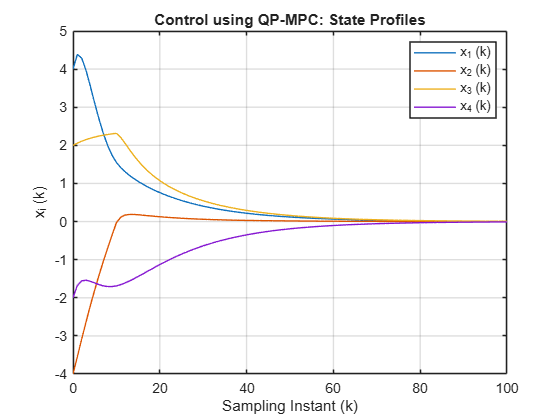

U_mimits = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;
Set_Graphics_Parameters ;   % This script file sets font size and line thickness for figures 
figure(1), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)'), title('Control using QP-MPC: State Profiles')

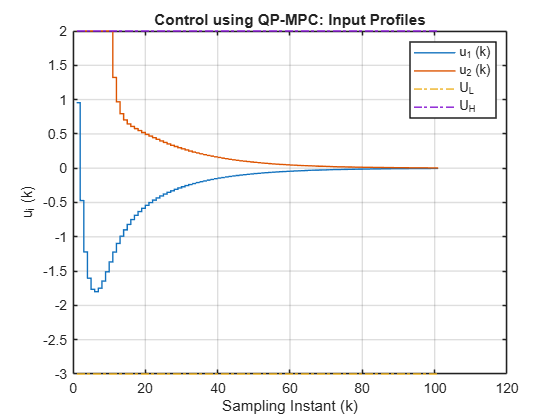

figure(2), stairs(uk', 'LineWidth',1), grid
hold on 
stairs(U_mimits, '-.', 'LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), title('Control using QP-MPC: Input Profiles')
legend('u_1 (k)', 'u_2 (k)', 'U_L', 'U_H')

Observe that the states are driven to the origin, irrespective of the initial condition.The controller outputs are within the specified upper and lower limits.

**Task 6:** Now change the operating point and again observe the results.

**Task 7: **Go to Task 2 and try changing the prediction horizon. Observe the effect on results.

**Task 8: **Go to Task 3 and try changing the weighting matrices. Observe the effect on results

### Reactor at Unstable Operating Point 

Now, let is look at another example: Continuous Stirred Tank Reactor (CSTR) system operated at the unstable operating point. The system dynamics are governed by the following


$$\left\lbrack \begin{array}{c}
{\delta C}_A \left(k+1\right)\\
\delta T\left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 7943 & -0\ldotp 006245\\
11\ldotp 93 & 1\ldotp 256
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\delta C}_A \left(k\right)\\
\delta T\left(k\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0\ldotp 001006 & 0\ldotp 09613\\
-0\ldotp 3673 & -3\ldotp 612
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\delta F}_C \left(k\right)\\
\delta F\left(k\right)
\end{array}\right\rbrack$$


Here, ${\delta C}_A \;\textrm{and}\;\delta T$ represent perturbations in concentration of reactant A and temperature, respectively. Manipulated inputs,  ${\delta F}_C \;\textrm{and}\;\delta F$represent coolant flow to the cooling jacket and flow of the reactant at the reactor inlet, respectively. 

### Closed Loop Simulation

 
clear all 

% CSTR System matrices at the unstable operating condition 
% Initialization of linear discrete time model for plant simulation 
phy=[0.7943 -0.006245 ; 11.93 1.256]; 
gam=[0.001006 0.09613; -0.3673 -3.612]';
[n_st,n_ip] = size(gam) ;

 Both the eigenvalues of $\Phi$ matrix lie outside the unit circle as  and the equilibrium point is unstable.

eig_val = eig(phy)

eig_val =    1.0252 + 0.1456i
   1.0252 - 0.1456i


abs(eig_val)

ans =     1.0354
    1.0354


% Initialization of Internal model for MPC 
mpc.phy = phy ;   
mpc.gam = gam ; 
[mpc.n_st,mpc.n_ip] = size(mpc.gam) ;

**MPC Tuning Parameters**

Prediction horizon n_pred is set to 15 and the state and input weighting matrices are set as follows.

 $W_x =\left\lbrack \begin{array}{cc}
10 & 0\\
0 & 1
\end{array}\right\rbrack$  $W_u =\left\lbrack \begin{array}{cc}
0\ldotp 1 & 0\\
0 & 1
\end{array}\right\rbrack$ and prediction horizon=15.

% MPC Tuning Parameters
mpc.n_pred = 15 ;     % Prediction interval 
mpc.Wx = diag( [ 10 1 ] ) ;    % State weighting matrix  
mpc.Wu =  diag( [0.1  1]) ;     % Input weighting matrix

For the CSTR system input flows are bound between 0 and 30 for coolant flow and 0 to 2 for reactant flow. Thus, bounds on perturbation inputs, with reference to $U_s ={\left\lbrack \begin{array}{cc}
3 & 3
\end{array}\right\rbrack }^T$can be defined as follows 

$u_H =\left\lbrack \begin{array}{c}
30\\
2
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
15\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
15\\
1
\end{array}\right\rbrack \;$  and $u_L =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
15\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-15\\
-1
\end{array}\right\rbrack$

We have written a code that  generates matrices needed for specifying these input constraints.  

mpc.u_H = [30 2]' - [ 15 1]' ;  % Flow Input bounds 
mpc.u_L = [0 0]' - [ 15 1 ]' ;  % Steady state inputs are [15 1] 
mpc.deluL = [] ; mpc.deluH = [] ; 

We then generate the matrices required for QP formulation. Controller calculations at instant $k$ are done assuming state vector is perfectly measured. 

% Generate QP matrices. Note: Program developed in Lesson 6 of Module 3 is made into a function 

[mpc.Sx_mat, mpc.Su_mat, mpc.H_mat, mpc.F_mat, mpc.A_mat, mpc.F_vec, mpc.B_mat] =...
    Gen_QP_Matrices(mpc.phy, mpc.gam, mpc.Wx, mpc.Wu, mpc.n_pred, mpc.u_L, mpc.u_H, mpc.deluL, mpc.deluH) ;

% Closed loop simulations using QP-LMPC under ideal conditions

N = 21 ;      % Simulation run time
xk = zeros(n_st,N);
xk(:,1) = [ 0.5 15 ]';
uk = zeros(n_ip,N) ;
options=optimoptions('quadprog', 'display', 'off');
for k = 1:N-1

    % Controller calculations at instant k assuming state vector is perfectly measured 
    kT(k) = (k-1);
  
    b_vec = mpc.F_vec ;
    mpc.xk = xk(:,k) ;   % Plant state is perfectly measured 
    % Terminal constraint 
    c1 = n_st*(mpc.n_pred-1) ;
    Aeq_mat = mpc.Su_mat(c1+1:c1+n_st,:) ;
    beq_vec = - mpc.Sx_mat(c1+1:c1+n_st,:) * mpc.xk ;
    [Uf_k,FVAL] = quadprog(mpc.H_mat, mpc.F_mat*mpc.xk, mpc.A_mat, b_vec, Aeq_mat, beq_vec,[],[],[],options )  ;
    mpc.uk = Uf_k(1:n_ip) ;  % Implement only optimal u(k) 

CSTR Simulation from  $k\;\textrm{to}\;k+1$ is done using a discrete linear model. 

    % CSTR Simulation from k to k+1 using discrete linear model 
    uk(:,k) = mpc.uk ;
    xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) ;
end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;

**Display Simulation Results **

Now observe the simulation results that show the state and input profiles plotted against time. Observe that the states are driven to the origin, irrespective of the initial condition. The controller outputs are within the specified upper and lower limits.

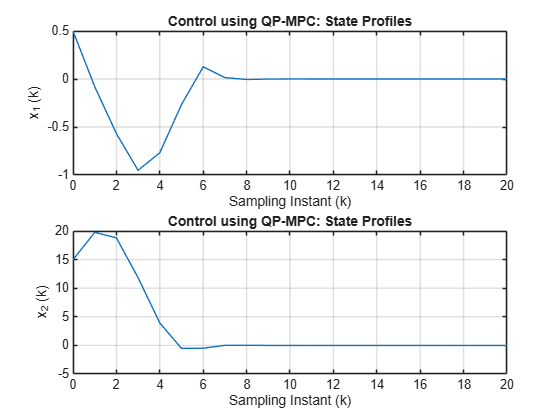

figure(3), subplot(211), plot(kT, xk(1,:)'), grid
xlabel('Sampling Instant (k)'), ylabel('x_1 (k)')
title('Control using QP-MPC: State Profiles')
figure(3), subplot(212), plot(kT, xk(2,:)'), grid
xlabel('Sampling Instant (k)'), ylabel('x_2 (k)')
title('Control using QP-MPC: State Profiles')

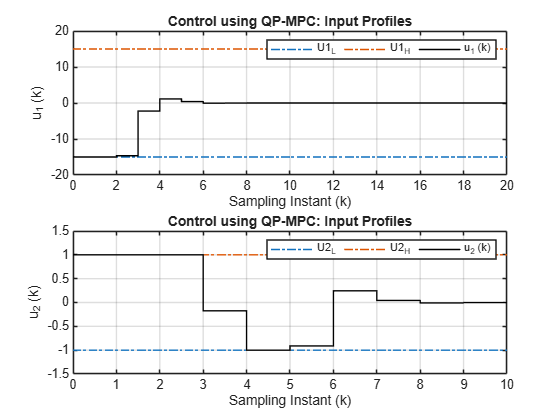

U1_mimits = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;
U2_mimits = [mpc.u_L(2)*ones(N,1) mpc.u_H(2)*ones(N,1)]  ;
figure(4), subplot(211), stairs(kT, U1_mimits, '-.', 'LineWidth',1), grid
hold on 
stairs(kT, uk(1,:)', 'k', 'LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_1 (k)'), title('Control using QP-MPC: Input Profiles')
legend( 'U1_L', 'U1_H', 'u_1 (k)', 'Orientation','horizontal')
figure(4), subplot(212), stairs(kT, U2_mimits, '-.', 'LineWidth',1), grid
axis([0 10 -1.5 1.5])
hold on 
stairs(kT, uk(2,:)', 'k','LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_2 (k)'), title('Control using QP-MPC: Input Profiles')
legend( 'U2_L', 'U2_H', 'u_2 (k)', 'Orientation','horizontal')

## Conclusion

Thus we have seen that a finite horizon constrained MPC can be formulated starting from infinite horizon LQOC formulation. To ensure the nominal stability, it is necessary to include the terminal constraints. However, inclusion of the terminal constraint can lead to in-feasibility of  QP. Thus, in most practical situations, MPC loss function with terminal cost included as in equation (22) is a preferred option. In the [next lesson](matlab:open('./L2_MPC_Target_Tracking.mlx')), we will start developing more practical variants of MPC. 

## References

-  Astrom, K. J. and B. Wittenmark, Computer Controlled Systems, Prentice Hall, 1990. 

- Franklin, G. F. and J. D. Powell, Digital Control of Dynamic Systems, Addison-Wesley, 1989

- [https://in.mathworks.com/discovery/optimal-control.html](https://in.mathworks.com/discovery/optimal-control.html)

- Muske, K.R., and J. B. Rawlings, Model Predictive Control with Linear Models, AIChE J, 39, 2, 1993. 

- Rawlings, J. B. and K. R. Muske, The Stability of Constrained Receding Horizon Control, IEEE Trans. on Automatic Control 38, 10, 1993. 